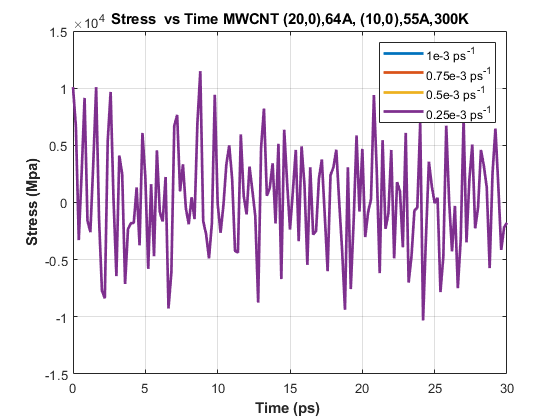

%%%swcnt
clc
clear all
close all


%%% fig 1 : Equilibration--time,etotal,pe,temp,pzz
%%%%% fig 2: deformation---time,etotal,pe,temp,strain,pzz

%%% MWCNT.300K.1.
MWCNTEqu1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.300K.1.Equi.txt','r');
MWCNTDef1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.300K.1.Deform.txt','r');
MWCNTEqu75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.300K.75.Equi.txt','r');
MWCNTDef75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.300K.75.Deform.txt','r');
MWCNTEqu5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.300K.5.Equi.txt','r');
MWCNTDef5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.300K.5.Deform.txt','r');
MWCNTEqu25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.300K.25.Equi.txt','r');
MWCNTDef25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.300K.25.Deform.txt','r');
MWCNTEqu01 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.300K.01.Equi.txt','r');
MWCNTDef01 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.300K.01.Deform.txt','r');

EquMWCNT1 = cell2mat(textscan(MWCNTEqu1,'%f%f%f%f%f','headerlines',1));
DefMWCNT1 =cell2mat(textscan(MWCNTDef1,'%f%f%f%f%f%f','headerlines',1));
EquMWCNT75 = cell2mat(textscan(MWCNTEqu75,'%f%f%f%f%f','headerlines',1));
DefMWCNT75 =cell2mat(textscan(MWCNTDef75,'%f%f%f%f%f%f','headerlines',1));
EquMWCNT5 = cell2mat(textscan(MWCNTEqu5,'%f%f%f%f%f','headerlines',1));
DefMWCNT5 =cell2mat(textscan(MWCNTDef5,'%f%f%f%f%f%f','headerlines',1));
EquMWCNT25 = cell2mat(textscan(MWCNTEqu25,'%f%f%f%f%f','headerlines',1));
DefMWCNT25 =cell2mat(textscan(MWCNTDef25,'%f%f%f%f%f%f','headerlines',1));
EquMWCNT01 = cell2mat(textscan(MWCNTEqu01,'%f%f%f%f%f','headerlines',1));
DefMWCNT01 =cell2mat(textscan(MWCNTDef01,'%f%f%f%f%f%f','headerlines',1));


fclose(MWCNTEqu1);
fclose(MWCNTDef1);
fclose(MWCNTEqu75);
fclose(MWCNTDef75);
fclose(MWCNTEqu5);
fclose(MWCNTDef5);
fclose(MWCNTEqu25);
fclose(MWCNTDef25);
fclose(MWCNTEqu01);
fclose(MWCNTDef01);

figure(1)  %%% equilibtration...stress vs time
plot(EquMWCNT1(:,1),EquMWCNT1(:,5),"LineWidth",2); 
hold on
plot(EquMWCNT75(:,1),EquMWCNT75(:,5),"LineWidth",2); 
hold on
plot(EquMWCNT5(:,1),EquMWCNT5(:,5),"LineWidth",2); 
hold on
plot(EquMWCNT25(:,1),EquMWCNT25(:,5),"LineWidth",2); 
 
title('Stress  vs Time MWCNT (20,0),64A, (10,0),55A,300K')
xlabel('Time (ps) ',"FontWeight","bold")
ylabel('Stress (Mpa)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}')
grid on
hold off

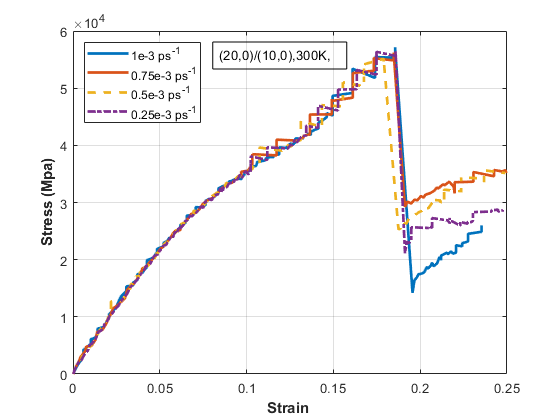

%%%%finding Sut...and yield strain
[Sut1,In1]= max(DefMWCNT1(:,6));Ys1=DefMWCNT1(In1,5);
[Sut2,In2]= max(DefMWCNT75(:,6));Ys2=DefMWCNT75(In2,5);
[Sut3,In3]= max(DefMWCNT5(:,6));Ys3=DefMWCNT5(In3,5);
[Sut4,In4]= max(DefMWCNT25(:,6));Ys4=DefMWCNT25(In4,5);
Sut_300= [Sut1 Sut2 Sut3 Sut4]'*1e-3;  % in Gpa
Ys_300= [Ys1 Ys2 Ys3 Ys4]';  % yield strain

figure(2);   %deformation
plot(DefMWCNT1(:,5),DefMWCNT1(:,6),"LineWidth",2); % strain vs stress
hold on
plot(DefMWCNT75(:,5),DefMWCNT75(:,6),"LineWidth",2);
hold on
plot(DefMWCNT5(:,5),DefMWCNT5(:,6),'--',"LineWidth",2);
hold on
plot(DefMWCNT25(:,5),DefMWCNT25(:,6),'-.',"LineWidth",2);


title('')
xlabel('Strain ',"FontWeight","bold")
ylabel('Stress (Mpa)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}','Location','northwest')
grid on
xlim([0 0.25])
ylim([0 6]*1e4)
annotation('textbox', [0.38, 0.8, 0.1, 0.1], 'String', "(20,0)/(10,0),300K,",'FitBoxToText',"on")
saveas(gcf,'C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\Graphs\Stress_vs_Strain200100300K.jpg')
 hold off

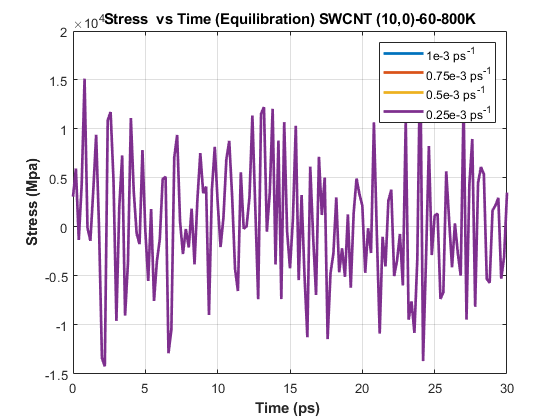



%%% fig 1 : Equilibration--time,etotal,pe,temp,pzz
%%%%% fig 2: deformation---time,etotal,pe,temp,strain,pzz

%%% MWCNT.800K
MWCNTEqu1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.800K.1.Equi.txt','r');
MWCNTDef1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.800K.1.Deform.txt','r');
MWCNTEqu75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.800K.75.Equi.txt','r');
MWCNTDef75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.800K.75.Deform.txt','r');
MWCNTEqu5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.800K.5.Equi.txt','r');
MWCNTDef5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.800K.5.Deform.txt','r');
MWCNTEqu25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.800K.25.Equi.txt','r');
MWCNTDef25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.800K.25.Deform.txt','r');
MWCNTEqu01 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.800K.01.Equi.txt','r');
MWCNTDef01 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.800K.01.Deform.txt','r');

EquMWCNT1 = cell2mat(textscan(MWCNTEqu1,'%f%f%f%f%f','headerlines',1));
DefMWCNT1 =cell2mat(textscan(MWCNTDef1,'%f%f%f%f%f%f','headerlines',1));
EquMWCNT75 = cell2mat(textscan(MWCNTEqu75,'%f%f%f%f%f','headerlines',1));
DefMWCNT75 =cell2mat(textscan(MWCNTDef75,'%f%f%f%f%f%f','headerlines',1));
EquMWCNT5 = cell2mat(textscan(MWCNTEqu5,'%f%f%f%f%f','headerlines',1));
DefMWCNT5 =cell2mat(textscan(MWCNTDef5,'%f%f%f%f%f%f','headerlines',1));
EquMWCNT25 = cell2mat(textscan(MWCNTEqu25,'%f%f%f%f%f','headerlines',1));
DefMWCNT25 =cell2mat(textscan(MWCNTDef25,'%f%f%f%f%f%f','headerlines',1));
EquMWCNT01 = cell2mat(textscan(MWCNTEqu01,'%f%f%f%f%f','headerlines',1));
DefMWCNT01 =cell2mat(textscan(MWCNTDef01,'%f%f%f%f%f%f','headerlines',1));


fclose(MWCNTEqu1);
fclose(MWCNTDef1);
fclose(MWCNTEqu75);
fclose(MWCNTDef75);
fclose(MWCNTEqu5);
fclose(MWCNTDef5);
fclose(MWCNTEqu25);
fclose(MWCNTDef25);
fclose(MWCNTEqu01);
fclose(MWCNTDef01);

figure(3)  %%% equilibtration...stress vs time
plot(EquMWCNT1(:,1),EquMWCNT1(:,5),"LineWidth",2); 
hold on
plot(EquMWCNT75(:,1),EquMWCNT75(:,5),"LineWidth",2); 
hold on
plot(EquMWCNT5(:,1),EquMWCNT5(:,5),"LineWidth",2); 
hold on
plot(EquMWCNT25(:,1),EquMWCNT25(:,5),"LineWidth",2); 

title('Stress  vs Time (Equilibration) SWCNT (10,0)-60-800K')
xlabel('Time (ps) ',"FontWeight","bold")
ylabel('Stress (Mpa)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}')
grid on
hold off

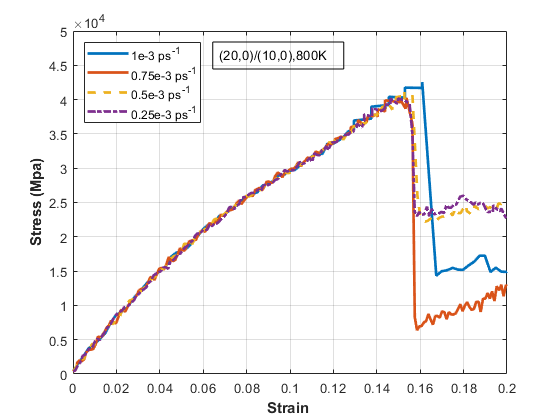

%%%%finding Sut...and yield strain
[Sut1,In1]= max(DefMWCNT1(:,6));Ys1=DefMWCNT1(In1,5);
[Sut2,In2]= max(DefMWCNT75(:,6));Ys2=DefMWCNT75(In2,5);
[Sut3,In3]= max(DefMWCNT5(:,6));Ys3=DefMWCNT5(In3,5);
[Sut4,In4]= max(DefMWCNT25(:,6));Ys4=DefMWCNT25(In4,5);
Sut_800= [Sut1 Sut2 Sut3 Sut4]'*1e-3;  % in Gpa
Ys_800= [Ys1 Ys2 Ys3 Ys4]';  % yield strain

figure(4);   %deformation
plot(DefMWCNT1(:,5),DefMWCNT1(:,6),"LineWidth",2); % strain vs stress
hold on
plot(DefMWCNT75(:,5),DefMWCNT75(:,6),"LineWidth",2);
hold on
plot(DefMWCNT5(:,5),DefMWCNT5(:,6),'--',"LineWidth",2);
hold on
plot(DefMWCNT25(:,5),DefMWCNT25(:,6),'-.',"LineWidth",2);


title('')
xlabel('Strain ',"FontWeight","bold")
ylabel('Stress (Mpa)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}','Location','northwest')
grid on
xlim([0 0.2])
ylim([-0 5]*1e4)
annotation('textbox', [0.38, 0.8, 0.1, 0.1], 'String', "(20,0)/(10,0),800K",'FitBoxToText',"on")
saveas(gcf,'C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\Graphs\Stress_vs_Strain200100800K.jpg')
hold off

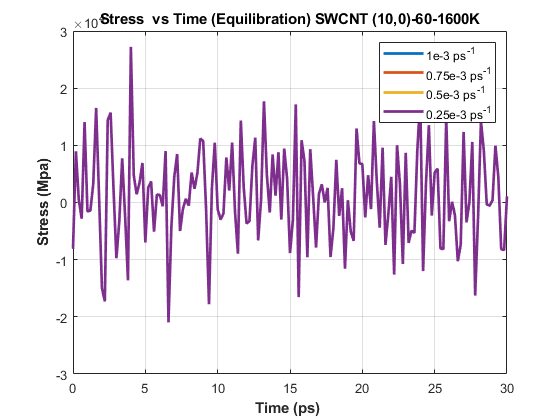


%%% fig 1 : Equilibration--time,etotal,pe,temp,pzz
%%%%% fig 2: deformation---time,etotal,pe,temp,strain,pzz

%%% MWCNT.1600K
MWCNTEqu1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.1600K.1.Equi.txt','r');
MWCNTDef1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.1600K.1.Deform.txt','r');
MWCNTEqu75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.1600K.75.Equi.txt','r');
MWCNTDef75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.1600K.75.Deform.txt','r');
MWCNTEqu5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.1600K.5.Equi.txt','r');
MWCNTDef5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.1600K.5.Deform.txt','r');
MWCNTEqu25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.1600K.25.Equi.txt','r');
MWCNTDef25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.1600K.25.Deform.txt','r');
MWCNTEqu01 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.1600K.01.Equi.txt','r');
MWCNTDef01 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.1600K.01.Deform.txt','r');


EquMWCNT1 = cell2mat(textscan(MWCNTEqu1,'%f%f%f%f%f','headerlines',1));
DefMWCNT1 =cell2mat(textscan(MWCNTDef1,'%f%f%f%f%f%f','headerlines',1));
EquMWCNT75 = cell2mat(textscan(MWCNTEqu75,'%f%f%f%f%f','headerlines',1));
DefMWCNT75 =cell2mat(textscan(MWCNTDef75,'%f%f%f%f%f%f','headerlines',1));
EquMWCNT5 = cell2mat(textscan(MWCNTEqu5,'%f%f%f%f%f','headerlines',1));
DefMWCNT5 =cell2mat(textscan(MWCNTDef5,'%f%f%f%f%f%f','headerlines',1));
EquMWCNT25 = cell2mat(textscan(MWCNTEqu25,'%f%f%f%f%f','headerlines',1));
DefMWCNT25 =cell2mat(textscan(MWCNTDef25,'%f%f%f%f%f%f','headerlines',1));
EquMWCNT01 =cell2mat(textscan(MWCNTEqu01,'%f%f%f%f%f','headerlines',1));
DefMWCNT01 =cell2mat(textscan(MWCNTDef01,'%f%f%f%f%f%f','headerlines',1));


fclose(MWCNTEqu1);
fclose(MWCNTDef1);
fclose(MWCNTEqu75);
fclose(MWCNTDef75);
fclose(MWCNTEqu5);
fclose(MWCNTDef5);
fclose(MWCNTEqu25);
fclose(MWCNTDef25);
fclose(MWCNTEqu01);
fclose(MWCNTDef01);

figure(5)  %%% equilibtration...stress vs time
plot(EquMWCNT1(:,1),EquMWCNT1(:,5),"LineWidth",2); 
hold on
plot(EquMWCNT75(:,1),EquMWCNT75(:,5),"LineWidth",2); 
hold on
plot(EquMWCNT5(:,1),EquMWCNT5(:,5),"LineWidth",2); 
hold on
plot(EquMWCNT25(:,1),EquMWCNT25(:,5),"LineWidth",2); 
 
title('Stress  vs Time (Equilibration) SWCNT (10,0)-60-1600K')
xlabel('Time (ps) ',"FontWeight","bold")
ylabel('Stress (Mpa)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}')
grid on
hold off

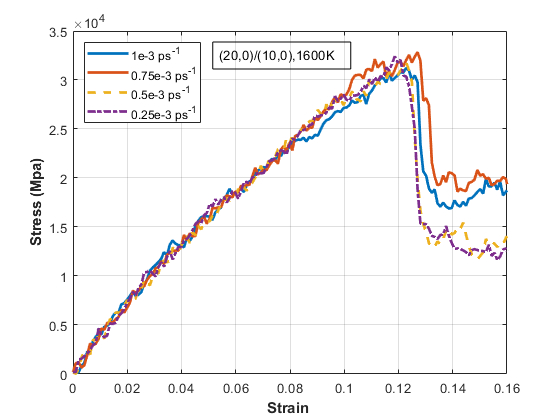

%%%%finding Sut...and yield strain
[Sut1,In1]= max(DefMWCNT1(:,6));Ys1=DefMWCNT1(In1,5);
[Sut2,In2]= max(DefMWCNT75(:,6));Ys2=DefMWCNT75(In2,5);
[Sut3,In3]= max(DefMWCNT5(:,6));Ys3=DefMWCNT5(In3,5);
[Sut4,In4]= max(DefMWCNT25(:,6));Ys4=DefMWCNT25(In4,5);
Sut_1600= [Sut1 Sut2 Sut3 Sut4]'*1e-3;  % in Gpa
Ys_1600= [Ys1 Ys2 Ys3 Ys4]';  % yield strain

figure(6);   %deformation
plot(DefMWCNT1(:,5),DefMWCNT1(:,6),"LineWidth",2); % strain vs stress
hold on
plot(DefMWCNT75(:,5),DefMWCNT75(:,6),"LineWidth",2);
hold on
plot(DefMWCNT5(:,5),DefMWCNT5(:,6),'--',"LineWidth",2);
hold on
plot(DefMWCNT25(:,5),DefMWCNT25(:,6),'-.',"LineWidth",2);

title('')
xlabel('Strain ',"FontWeight","bold")
ylabel('Stress (Mpa)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}','Location','northwest')
grid on
xlim([0 0.16])
ylim([0 3.5]*1e4)
annotation('textbox', [0.38, 0.8, 0.1, 0.1], 'String', "(20,0)/(10,0),1600K",'FitBoxToText',"on")
saveas(gcf,'C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\Graphs\Stress_vs_Strain2001001000K.jpg')
hold off

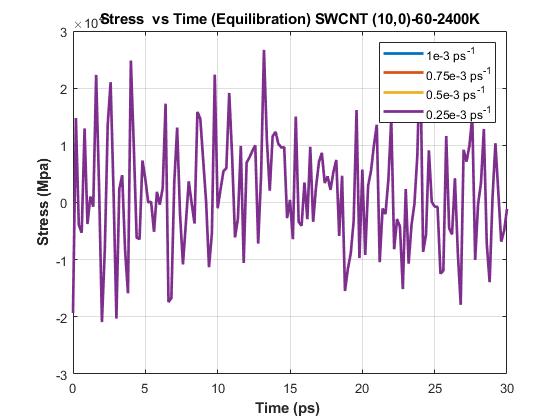

%%% MWCNT.2400K

%%% fig 1 : Equilibration--time,etotal,pe,temp,pzz
%%%%% fig 2: deformation---time,etotal,pe,temp,strain,pzz

%%% MWCNT.2400K
MWCNTEqu1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.2400K.1.Equi.txt','r');
MWCNTDef1 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.2400K.1.Deform.txt','r');
MWCNTEqu75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.2400K.75.Equi.txt','r');
MWCNTDef75 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.2400K.75.Deform.txt','r');
MWCNTEqu5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.2400K.5.Equi.txt','r');
MWCNTDef5 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.2400K.5.Deform.txt','r');
MWCNTEqu25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.2400K.25.Equi.txt','r');
MWCNTDef25 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.2400K.25.Deform.txt','r');
MWCNTEqu01 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.2400K.01.Equi.txt','r');
MWCNTDef01 =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\MWCNT.2400K.01.Deform.txt','r');

EquMWCNT1 = cell2mat(textscan(MWCNTEqu1,'%f%f%f%f%f','headerlines',1));
DefMWCNT1 =cell2mat(textscan(MWCNTDef1,'%f%f%f%f%f%f','headerlines',1));
EquMWCNT75 = cell2mat(textscan(MWCNTEqu75,'%f%f%f%f%f','headerlines',1));
DefMWCNT75 =cell2mat(textscan(MWCNTDef75,'%f%f%f%f%f%f','headerlines',1));
EquMWCNT5 = cell2mat(textscan(MWCNTEqu5,'%f%f%f%f%f','headerlines',1));
DefMWCNT5 =cell2mat(textscan(MWCNTDef5,'%f%f%f%f%f%f','headerlines',1));
EquMWCNT25 = cell2mat(textscan(MWCNTEqu25,'%f%f%f%f%f','headerlines',1));
DefMWCNT25 =cell2mat(textscan(MWCNTDef25,'%f%f%f%f%f%f','headerlines',1));
EquMWCNT01 = cell2mat(textscan(MWCNTEqu01,'%f%f%f%f%f','headerlines',1));
DefMWCNT01 =cell2mat(textscan(MWCNTDef01,'%f%f%f%f%f%f','headerlines',1));


fclose(MWCNTEqu1);
fclose(MWCNTDef1);
fclose(MWCNTEqu75);
fclose(MWCNTDef75);
fclose(MWCNTEqu5);
fclose(MWCNTDef5);
fclose(MWCNTEqu25);
fclose(MWCNTDef25);
fclose(MWCNTEqu01);
fclose(MWCNTDef01);

figure(7)  %%% equilibtration...stress vs time
plot(EquMWCNT1(:,1),EquMWCNT1(:,5),"LineWidth",2); 
hold on
plot(EquMWCNT75(:,1),EquMWCNT75(:,5),"LineWidth",2); 
hold on
plot(EquMWCNT5(:,1),EquMWCNT5(:,5),"LineWidth",2); 
hold on
plot(EquMWCNT25(:,1),EquMWCNT25(:,5),"LineWidth",2); 

title('Stress  vs Time (Equilibration) SWCNT (10,0)-60-2400K')
xlabel('Time (ps) ',"FontWeight","bold")
ylabel('Stress (Mpa)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}')
grid on
hold off

%%%%finding Sut...and yield strain
[Sut1,In1]= max(DefMWCNT1(:,6));Ys1=DefMWCNT1(In1,5);
[Sut2,In2]= max(DefMWCNT75(:,6));Ys2=DefMWCNT75(In2,5);
[Sut3,In3]= max(DefMWCNT5(:,6));Ys3=DefMWCNT5(In3,5);
[Sut4,In4]= max(DefMWCNT25(:,6));Ys4=DefMWCNT25(In4,5);
Sut_2400= [Sut1 Sut2 Sut3 Sut4]'*1e-3;  % in Gpa
Ys_2400= [Ys1 Ys2 Ys3 Ys4]';  % yield strain


Ys_MWCNT= [Ys_300,Ys_800,Ys_1600,Ys_2400]     %yield strain

Ys_MWCNT =     0.1856    0.1609    0.1228    0.1060
    0.1847    0.1537    0.1270    0.1012
    0.1790    0.1527    0.1228    0.1040
    0.1858    0.1497    0.1186    0.0924


Sut_MWCNT= [Sut_300,Sut_800,Sut_1600,Sut_2400]       % ultimate strenth

Sut_MWCNT =    57.1540   42.5519   31.2346   33.2784
   56.2304   40.2576   32.8403   30.2103
   55.1935   41.1430   31.7816   30.7699
   56.4583   40.1597   32.4106   28.9946


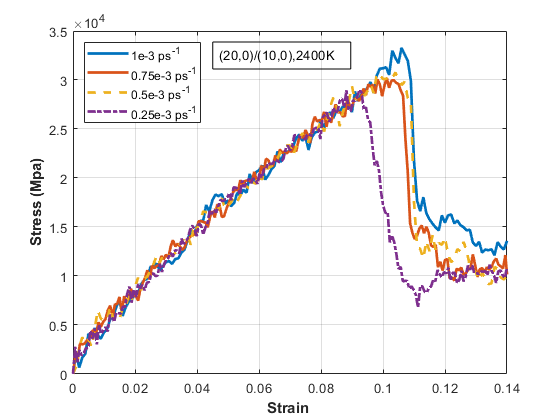

writematrix(Sut_MWCNT,'C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\Sut_MWCNT.txt','Delimiter','tab')
writematrix(Ys_MWCNT,'C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\Ys_MWCNT.txt','Delimiter','tab')


figure(8);   %deformation
plot(DefMWCNT1(:,5),DefMWCNT1(:,6),"LineWidth",2); % strain vs stress
hold on
plot(DefMWCNT75(:,5),DefMWCNT75(:,6),"LineWidth",2);
hold on
plot(DefMWCNT5(:,5),DefMWCNT5(:,6),'--',"LineWidth",2);
hold on
plot(DefMWCNT25(:,5),DefMWCNT25(:,6),'-.',"LineWidth",2);


title('')
xlabel('Strain ',"FontWeight","bold")
ylabel('Stress (Mpa)',"FontWeight","bold")
legend('1e-3 ps^{-1}','0.75e-3 ps^{-1}','0.5e-3 ps^{-1}','0.25e-3 ps^{-1}','Location','northwest')
grid on
xlim([0 0.14])
ylim([0 3.5]*1e4)
annotation('textbox', [0.38, 0.8, 0.1, 0.1], 'String', "(20,0)/(10,0),2400K",'FitBoxToText',"on")
saveas(gcf,'C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\Graphs\Stress_vs_Strain2001002400K.jpg')
hold off